clf;
%%Testskript für die Blattauslegung mit Betz/Schmitz
%%zum erstellen eines neuen Profils Rotorradius, schnelllaufzahl und
%%Blattanzahl. Danach noch den profilnamen eingeben (z. Zt. gehen nur NACA
%%4-Digit Profile. der Radius bei dem das Profil hinzugefügt werden soll, 
%%Anstellwinkel,  und Postion der Blattachse eingeben. Zum Bearbeiten muss
%%"edit" auf 1 gesetzt sein. Ansonsten werden nur vorhanden Profile
%%geplottet

%%globale Variablen des Rotors
R=50;           %%Rotorradius [m]
lamda_A=7;      %%Schnelllaufzahl   [1]
z=3;            %%Blattanzahl       [1}

%%lokale Variablen zum einfgügen der Profile
name='naca64208';    %%Profilname gerade nur NACA 4-digit profile, z.B. "NACA0012", oder "Cir_2.1" für 2.1m kreis
%%alpha_A=6;          %%Anstellwinkel     [°]
t=0.25;             %%Position Blattachse
r=40;               %%Position des Profils auf dem Blatt

edit=1;             %%edit an oder aus


## load foildatabase

fileName='foils_imported.dat';

foil_db=readtable(fileName)

foil_db = 12×7 table
      foil_name       AoA_eps    CL_eps    CD_eps     AoA_lift    CL_lift    CD_lift
    ______________    _______    ______    _______    ________    _______    _______

    {'fx84w097'  }       7       1.0105    0.01803       11       1.1829     0.05986
    {'fx84w127'  }       9       1.2775    0.02398       14       1.3242     0.06805
    {'n63212'    }       6       0.7485    0.01722        9       0.9323     0.04305
    {'naca1408'  }       4        0.579    0.01308        8       0.8962     0.04622
    {'naca1410'  }       5       0.6834    0.01528       10       1.0252     0.05438
    {'naca1412'  }       6       0.7861    0.01776       11       1.1294     0.04802
    {'naca23012' }       5       0.7214    0.02052       12 

## check if foil exists in db

Index =find(strcmp(name,foil_db.foil_name))

Index = 10

## Profile erstellen und anhängen

if edit==1
   if exist('prof')==0
       prof(1)=profile_transform(R,r,name,lamda_A,z, t,foil_db);
   else
       if check_existing(prof,r) == 0
            l=length(prof);
            prof(l+1)=profile_transform(R,r,name,lamda_A,z, t,foil_db);
            prof=bld_sort(prof);
       else
           disp('Profil an dieser Blattposition existiert bereits. Anderen Profilposition waehlen!')
       end
   end
end

existing = logical
   0


Index = 10

profile =     1.0000    0.9501    0.9002    0.8503    0.8003    0.7503    0.7003    0.6503    0.6002    0.5501    0.5000    0.4499    0.3997    0.3496    0.2995    0.2493    0.1992    0.1492    0.0991    0.0741    0.0491    0.0242    0.0118    0.0069    0.0044         0    0.0056    0.0081    0.0132    0.0258    0.0509    0.0759    0.1009    0.1509    0.2008    0.2506    0.3005    0.3504    0.4003    0.4501    0.5000    0.5499    0.5998    0.6497    0.6997    0.7497    0.7997    0.8497    0.8998    0.9499
         0    0.0052    0.0107    0.0163    0.0220    0.0275    0.0326    0.0373    0.0415    0.0451    0.0479    0.0498    0.0506    0.0501    0.0486    0.0460    0.0423    0.0374    0.0309    0.0268    0.0219    0.0155    0.0111    0.0086    0.0071         0   -0.0061   -0.0072   -0.0090   -0.0118   -0.0156   -0.0183   -0.0205   -0.0239   -0.0264   -0.0281   -0.0291   -0.0295   -0.0292   -0.0279   -0.0258   -0.0232   -0.0201   -0.0167   -0.0132   -0.0096   -0.0061   -0.0029   -0.000

theta_bld = 0.0480

deep_bld = 4.2885

rot_angle = 0.1178

profile =     3.1941    2.9789    2.7636    2.5482    2.3325    2.1169    1.9013    1.6858    1.4705    1.2554    1.0406    0.8261    0.6122    0.3990    0.1862   -0.0259   -0.2375   -0.4483   -0.6583   -0.7626   -0.8665   -0.9694   -1.0200   -1.0397   -1.0493   -1.0647   -1.0380   -1.0265   -1.0040   -0.9489   -0.8402   -0.7322   -0.6246   -0.4102   -0.1964    0.0169    0.2298    0.4424    0.6546    0.8663    1.0777    1.2888    1.4998    1.7108    1.9218    2.1328    2.3441    2.5555    2.7675    2.9801
    0.3780    0.3751    0.3732    0.3721    0.3711    0.3693    0.3659    0.3607    0.3533    0.3432    0.3299    0.3127    0.2911    0.2635    0.2317    0.1955    0.1546    0.1085    0.0555    0.0255   -0.0080   -0.0478   -0.0728   -0.0858   -0.0937   -0.1260   -0.1490   -0.1527   -0.1575   -0.1631   -0.1667   -0.1658   -0.1627   -0.1520   -0.1372   -0.1193   -0.0986   -0.0750   -0.0487   -0.0179    0.0161    0.0525    0.0907    0.1302    0.1705    0.2110    0.2512    0.2900    0.326

foil_temp = struct with fields:
       x: [1×51 double]
       y: [1×51 double]
       z: [40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40 40]
    name: 'naca64208'


## plot der profile

bld_plot(prof)

l = 8

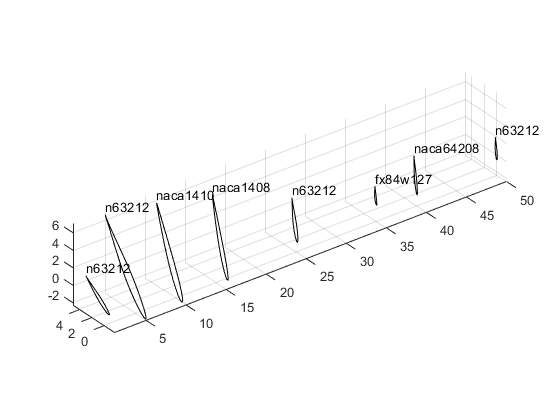

grid on